## **Driver test program to check Clothoids library**

**Test clothoid**

% check constructors
x0     = 0;
y0     = 2;
x1     = 3;
y1     = 3;
x2     = 5;
y2     = 2;
theta0 = 0;
theta1 = pi;
L      = 10;
k0     = 1/3;
dk     = 0;

L1 = ClothoidCurve( x0, y0, theta0, k0, dk, L );
L2 = ClothoidCurve();
L2.build_G1( x0, y0, theta0, x1, y1, theta1 );
L3 = ClothoidCurve();
L3.build_G1( x0, y0, theta0, x2, y2, theta1 );

%
npts = 1000;
L1.plot();
hold on;
L2.plot(npts,'Color','red','LineWidth',3);
L3.plot(npts,'Color','black','LineWidth',3);

L1.translate(1,1);
L1.plot();

L2.changeCurvilinearOrigin(-4,10);
L2.plot(npts,'Color','red','LineWidth',3);


L2.changeCurvilinearOrigin(1,2);
L2.plot(npts,'Color','red','LineWidth',3);

L3.trim(2,7);
L3.plot(npts,'Color','green','LineWidth',3);

L3.rotate(pi/3,0,0);
L3.plot(npts,'Color','green','LineWidth',3);

L3.rotate(pi/3,0,0);
L3.plot(npts,'Color','green','LineWidth',3);

L3.rotate(pi/3,0,0);
L3.plot(npts,'Color','green','LineWidth',3);

L3.translate(3,3);
L3.plot(npts,'Color','blue','LineWidth',3);

L3.eval(1)
L3.eval_D(1)
L3.eval_DD(1)
L3.eval_DDD(1)
L3.xBegin()

ans =    1.185249278933250


L3.yBegin()

ans =    0.247172937347076


L3.thetaBegin()

ans =    3.784925101775229


L3.length()

ans =      5


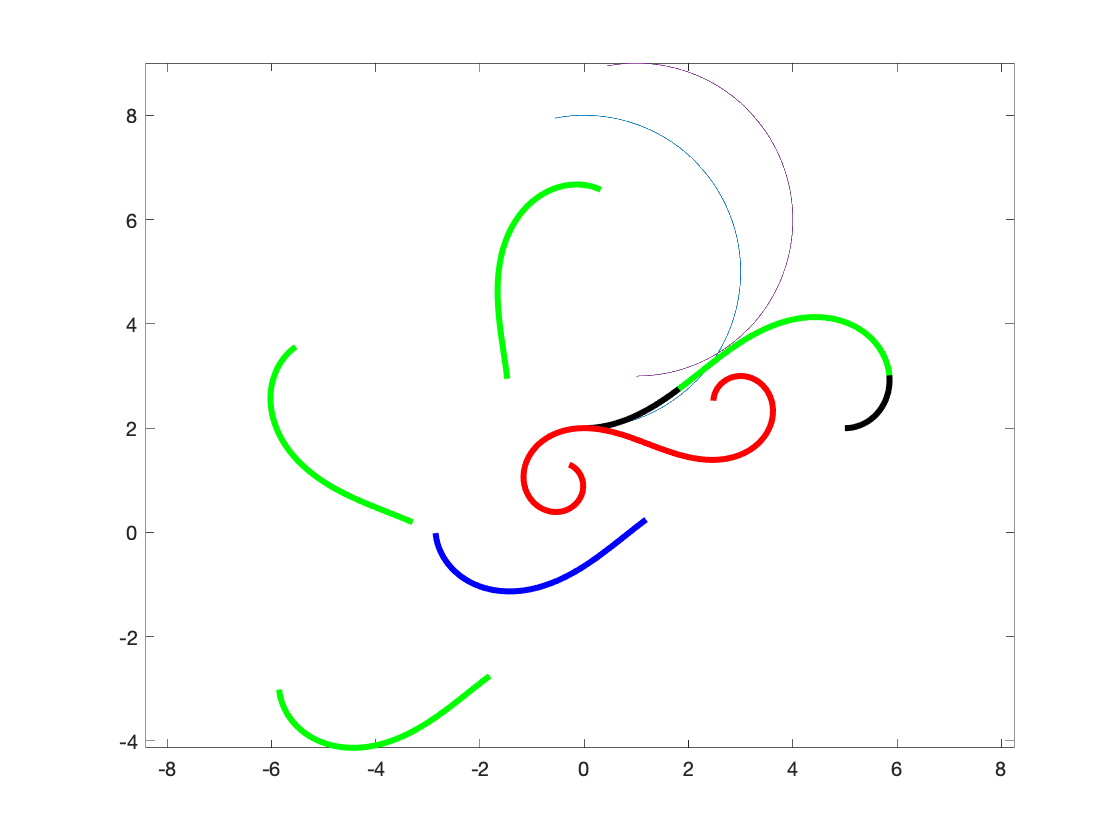


%L3.distance(1,4)

axis equal;

%